# Report_31_61_65_67 : 2D-Rigid Body Ballistic Pose Estimation w / IMU

## 1. Problem Formulation

ต้องการสร้างระบบจำลองการประมาณค่าตำแหน่งและทิศทางการหมุนของวัตถุที่ถูกโยนจากข้อมูลเซนเซอร์ IMU ที่ติดอยู่บนวัตถุโดยมีเงื่อนไขดังนี้

###     **1.1 เงื่อนไขลักษณะวัตถุ**

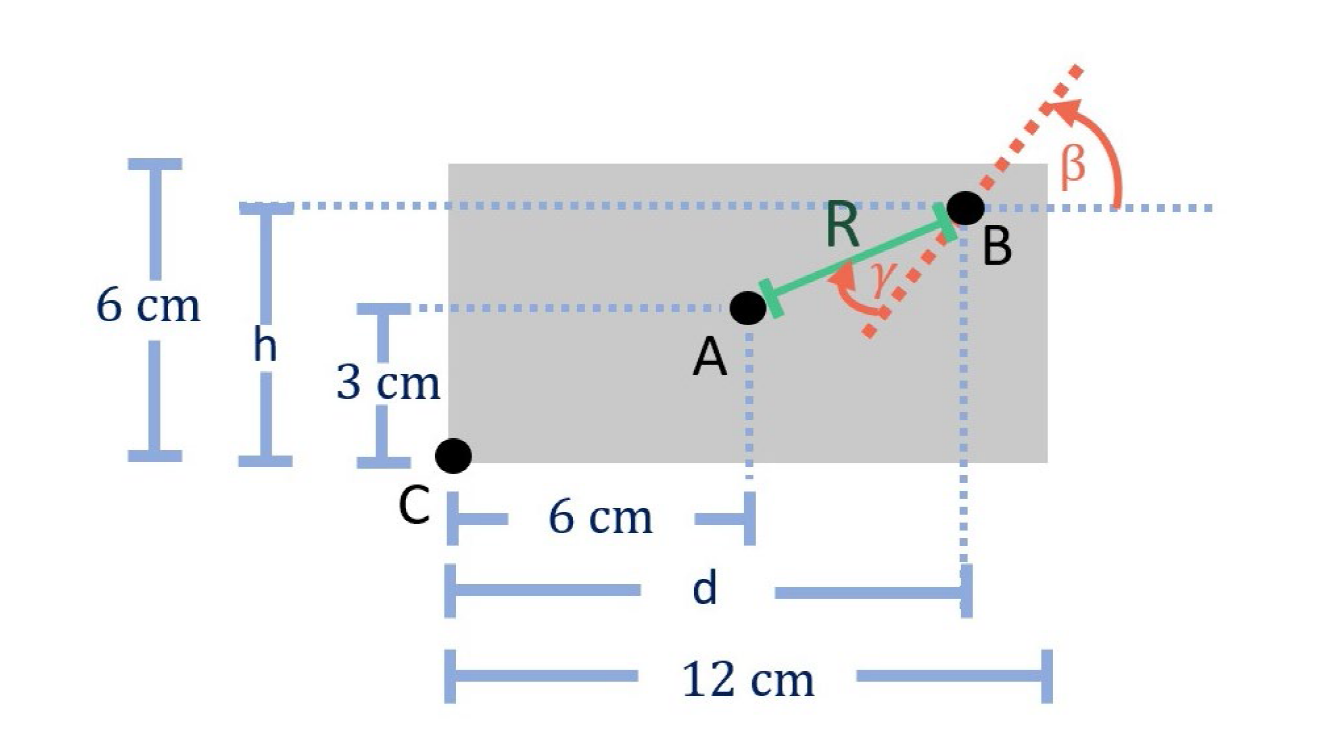

รูปที่ 1 ขนาดและตำแหน่งจุดบนวัตถุ

    - กำหนดจุด A คือ จุดศูนย์กลางมวลรวม (CM) หรือจุดระบุตำแหน่งของวัตถุ, จุด B คือ ตำแหน่งเซนเซอร์ IMU, จุด C คือ อ้างอิงตำแหน่งของวัตถุ

    - วัตถุมีรูปร่างเป็นสี่เหลี่ยมผืนผ้าที่มีขนาด 6 x 12 x 1 [cm] และกำหนดให้ d คือ ระยะห่างของ IMU เทียบกับขอบวัตถุในแนวแกน $X_M$ , h คือ ระยะห่างของ IMU เทียบกับขอบวัตถุในแนวแกน $Y_M$ , β คือ มุมเอียงของเซนเซอร์จากวัตถุ

    - กำหนดให้เซนเซอร์เป็นจุด ไม่มีขนาดและมวล

    - วัตถุเป็นวัตถุแข็งเกร็งมีความหนาแน่นกระจายตัวเท่ากันทั้งก้อน (รวมวัตถุและเซนเซอร์ IMU) ดังนั้นจุดศูนย์กลางมวลรวม (CM) ของวัตถุและเซนเซอร์ IMU จึงอยู่ที่จุด A ดังรูปที่ 1

###     1.2 เงื่อนไขสภาพแวดล้อมและการเคลื่อนที่

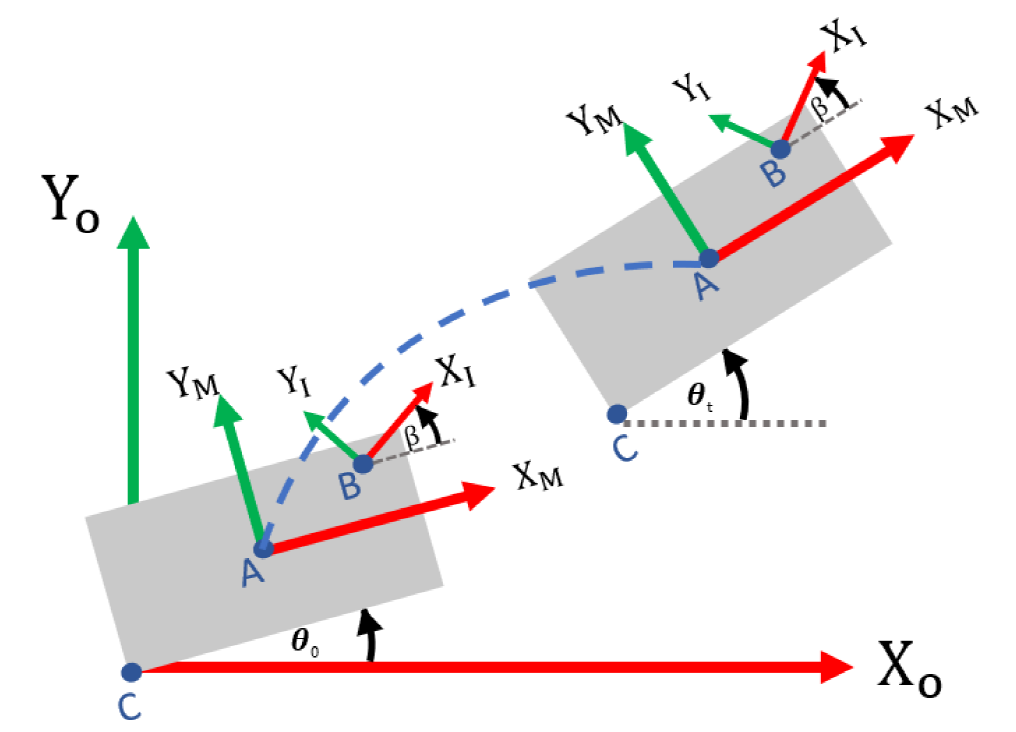

รูปที่ 2 การวางพิกัดเฟรมและรูปแบบการเคลื่อนที่ของวัตถุ

    - ให้พิกัดเฟรมโลกในการวัดตำแหน่งวัตถุ ($F_0$ ) ยึดติดกับพื้นโลกมีทิศของแกน $X_0$  และ $Y_0$  ดังรูปที่ 2

    - ให้เฟรมวัตถุมีจุดกำเนิดอยู่ที่จุดศูนย์กลางมวลของวัตถุ ($F_M$ ) มีทิศของแกน $X_M$  และ $Y_M$  ดังรูปที่ 2

    - ให้เฟรมเซนเซอร์มีจุดกำเนิดอยู่ที่ตำแหน่งเซนเซอร์ ($F_I$ ) มีทิศของแกน $X_I$  และ $Y_I$  ดังรูปที่ 2

    - มีแรงโน้มถ่วงทิศทางตรงกันข้ามกับแกน $Y_0$  และมีขนาด 9.81 $m/s^2$

    - แกน $Z$ ของ IMU มีทิศทางเดียวกันกับแกน $Z$ ของเฟรมโลก

    - วัตถุนี้จะเคลื่อนที่ไปในระนาบ $X_0 Y_0$  และมีการหมุนรอบแกน $Z_M$  เพียงแกนเดียว

    - การเคลื่อนที่ของวัตถุมีการหมุนรอบจุดศูนย์กลางมวลด้วยความเร็วเชิงมุมคงที่ และ ตำแหน่งจุดศูนย์กลางมวลมีการเคลื่อนที่แบบโพรเจกไทล์เนื่องจากกำหนดให้ระบบไม่มีแรงต้านอากาศกระทำกับวัตถุ

###     1.3 เงื่อนไขค่าเริ่มต้น

    - ตำแหน่งเริ่มต้นและทิศทางหมุนเริ่มต้นในการโยนคือ จุด C บนวัตถุอยู่ตำแหน่ง (0, 0) บนเฟรมโลก และวัตถุทำมุม $\frac{\pi }{6}$ [rad] กับแกน $X_0$ และจากเงื่อนไขที่ระบุมาทำให้สามารถระบุตัวแปรและพารามิเตอร์ได้ดังนี้

    ตัวแปรต้น: เวลา (𝑡) [sec]

    ตัวแปรตาม: ทิศการหมุนของวัตถุ (θ) [rad], ตำแหน่งของจุด CM ($\overset{\rightharpoonup }{p_{\textrm{CM}} }$) [m] เทียบกับเฟรมโลก

    ตัวแปรควบคุม: แรงโน้มถ่วง (𝑔) [$m/s^2$]

    พารามิเตอร์: ระยะห่างระหว่างเซนเซอร์กับมุมซ้ายล่างของวัตถุ (h,d), ระยะจากจุด B ไป A (𝑅) [cm], มุมเอียงของเซนเซอร์จากวัตถุ (β), มุมที่เวกเตอร์จากจุด B ไป A ทำกับแกน $Y_M$ (𝛾)

## 2. แนวทางการพัฒนาโดยรวม

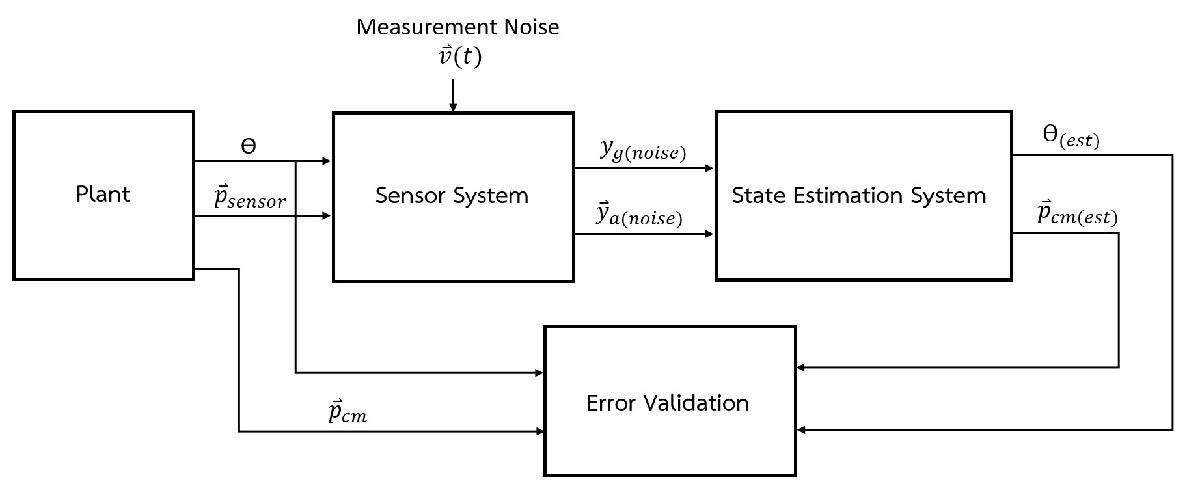

รูปที่ 3 ภาพรวมระบบ

1. จำลองระบบทางกายภาพที่ (Plant) ส่งข้อมูลออกมาเป็นทิศการหมุนของวัตถุ (θ) [rad] และตำแหน่งของเซนเซอร์ (${\overset{\rightharpoonup }{p} }_{\textrm{sensor}}$) [m] บนเฟรมโลกโดยมองว่าไม่เกิด noise จากระบบทางกายภาพ

2. นำข้อมูลจากระบบทางกายภาพ (Plant) เข้าสู่ระบบจำลองเซนเซอร์ (Sensor System) เพื่อทำการจำลองสัญญาณความเร่งเชิงเส้น ($\overset{\rightharpoonup }{y_a }$) และความเร็วเชิงมุม ($\overset{\rightharpoonup }{y_g }$) ที่อ่านได้จากเซนเซอร์ IMU โดยเซนเซอร์ที่จำลองมี noise แบบ Gaussian Distribution (f~N(0,0.01), ω~N(0,0.01))

3. นำข้อมูลจากระบบจำลองเซนเซอร์ (Sensor System) เข้าสู่ระบบประมาณค่า (State Estimation System) เพื่อประมาณค่า State ทิศทางการหมุนและตำแหน่งของวัตถุ โดยใช้ Kalman Filter แบบ Discrete Time ซึ่งมีรูปแบบของสมการดังนี้ 

    
$$x\left\lbrack n+1\right\rbrack =A\left\lbrack n\right\rbrack x\left\lbrack n\right\rbrack +B\left\lbrack n\right\rbrack u\left\lbrack n\right\rbrack +G\left\lbrack n\right\rbrack w\left\lbrack n\right\rbrack$$


    
$$y\left\lbrack n\right\rbrack =C\left\lbrack n\right\rbrack x\left\lbrack n\right\rbrack +D\left\lbrack n\right\rbrack u\left\lbrack n\right\rbrack +H\left\lbrack n\right\rbrack w\left\lbrack n\right\rbrack +v\left\lbrack n\right\rbrack$$


    ซึ่ง Kalman Filter ที่ทำจะแบ่งออกเป็น 2 ส่วน คือ

        - Time-Invariant Kalman Filter ใช้เพื่อประมาณค่ามุมและความเร็วเชิงมุมของวัตถุ เนื่องจากสัมประสิทธิ์ในสมการของ Kalman Filter เป็นค่าคงที่ตลอดการจำลอง

        - Time-Variant Kalman Filter ใช้เพื่อประมาณค่าตำแหน่ง, ความเร็ว และความเร่งของวัตถุเมื่อเทียบกับแกนโลก เนื่องจากสัมประสิทธิ์ในสมการของ Kalman Filter มีการเปลี่ยนแปลงตามมุมและความเร็วเชิงมุมของวัตถุระหว่างการจำลอง

4. วิเคราะห์ผลที่ได้จากระบบประมาณค่า (State Estimation System) โดยการนำมาเทียบกับข้อมูลจากระบบทางกายภาพ (Plant) ด้วยระบบตรวจสอบความคลาดเคลื่อน (Error Validation)

## 3. แบบจำลองระบบ

###     3.1 นิยามตัวแปรใน simulink     

####          Constant Parameter

            l_box ($L_b$) = ความยาววัตถุ [$m$]

            h_box ($H_b$) = ความสูงวัตถุ [$m$]

            l_sensor ($L_s$) = ระยะ d [$m$]

            h_sensor ($H_s$) = ระยะ h [$m$]

            g = แรงโน้มถ่วงในทิศชี้ลง [$m/s^2$]

            theta0 ($\theta_0$) = มุมที่วัตถุเอียงเมื่อเทียบกับเฟรมโลกที่ตำแหน่งเริ่มต้น [rad]  

            w0 ($w_0$) = ความเร็วเชิงมุมของเซนเซอร์ที่ตำแหน่งเริ่มต้น [rad/s]

            v0 ($v_0$) = ความเร็วเชิงเส้นของจุดศูนย์กลางมวลของวัตถุที่ตำแหน่งเริ่มต้น [$m/s$]

            theta_v0 ($\theta_{v_0 }$)  = มุมที่ v0 กระทำกับวัตถุเมื่อเทียบกับเฟรมโลกที่ตำแหน่งเริ่มต้น [rad]

            beta ($\beta$) = มุมเอียงของเซนเซอร์เมื่อเทียบกับแกนความยาววัตถุ [rad]

            gamma ($\gamma$) = มุมที่ $\overrightarrow{\textrm{BA}}$ เมื่อเทียบกับแกน $Y_I$ ในทิศทวนเข็ม [rad]

            delta_t = time step [$s$]

####         Plant Parameter

            theta_sensor/box ($\theta_{s/b}$) = มุมของ $\overset{\rightharpoonup }{\textrm{AB}}$ เมื่อเทียบกับแกน $X_M$ ในทิศ -$\hat{k}$ [rad]

            l_sensor/cm ($l_{s/\textrm{cm}}$) = ระยะห่างระหว่างตำแหน่งเซนเซอร์กับจุดศูนย์กลางมวลบนแกน $X_M$ [$m$]

            h_sensor/cm ($h_{s/\textrm{cm}}$) = ระยะห่างระหว่างตำแหน่งเซนเซอร์กับจุดศูนย์กลางมวลบนแกน $Y_M$ [$m$]

            R = ขนาดของ $\overset{\rightharpoonup }{\textrm{AB}}$ [$m$]

####          Plant Variable

            theta_box/world ($\theta_{b/w}$) = มุมที่แกน $X_0$ ทำมุมกับแกน $X_M$ ในทิศ $\hat{k}$ [rad]

            posX_cm/world ($p_{x,\textrm{cm}/w}$) = ตำแหน่งบนแกน X ของจุดศูนย์กลางมวลเมื่อเทียบกับเฟรมโลก [$m$]

            posY_cm/world ($p_{y,\textrm{cm}/w}$) = ตำแหน่งบนแกน Y ของจุดศูนย์กลางมวลเมื่อเทียบกับเฟรมโลก [$m$]

            pos_cm/world ($p_{\textrm{cm}/w}$) = เวกเตอร์ตำแหน่งของจุดศูนย์กลางมวลเมื่อเทียบกับเฟรมโลก [$m$]  

            posX_sensor/box ($p_{x,s/b}$) = ระยะห่างระหว่างตำแหน่งของเซนเซอร์กับจุดศูนย์กลางมวลบนแกน $X_0$ [$m$]

            posY_sensor/box ($p_{y,s/b}$) = ระยะห่างระหว่างตำแหน่งของเซนเซอร์กับจุดศูนย์กลางมวลบนแกน $Y_0$ [$m$]

            posX_sensor/world ($p_{x,s/w}$) = ตำแหน่งบนแกน X ของจุดศูนย์เซนเซอร์เมื่อเทียบกับเฟรมโลก [$m$]

            posY_sensor/world ($p_{y,s/w}$) = ตำแหน่งบนแกน Y ของจุดศูนย์เซนเซอร์เมื่อเทียบกับเฟรมโลก [$m$]

####         Sensor Parameter

            a0_sensor ($a_{0,s}$) = ความเร่งเชิงเส้นของเซนเซอร์บนเฟรมโลกที่ตำแหน่งเริ่มต้น [$m/s^2$]

            v0_sensor ($v_{0,s}$) = ความเร็วเชิงเส้นของเซนเซอร์บนเฟรมโลกที่ตำแหน่งเริ่มต้น [$m/s$]

####         Sensor Valiable

            aX_sensor/world ($a_{x,s/w}$) = ความเร่งของเซนเซอร์บนแกน $X_0$ [$m/s^2$]

            aY_sensor/world ($a_{y,s/w}$) = ความเร่งของเซนเซอร์บนแกน $Y_0$ [$m/s^2$]

            theta_sensor/world ($\theta_{s/w}$) = มุมที่แกน $X_0$ ทำมุมกับแกน $X_I$ ในทิศ $\hat{k}$ [rad]ุ 

            acc ($a_{\textrm{acc}}$) = เวกเตอร์ความเร่งของเซนเซอร์บนเฟรมเซนเซอร์[$m/s^2$]

            w_gyro ($w_{\textrm{gyro}}$) = ความเร็วเชิงมุมของเซนเซอร์ ในทิศ $\hat{k}$ [rad/s]

####        Time-Invariant Kalman Filter Parameter

            A_I = สัมประสิทธิ์ A ของ Time-Invariant Kalman Filter

            C_I = สัมประสิทธิ์ C ของ Time-Invariant Kalman Filter

            G_I = สัมประสิทธิ์ G ของ Time-Invariant Kalman Filter

            H_I = สัมประสิทธิ์ H ของ Time-Invariant Kalman Filter

            R_I = Covariance ของ Measurement Noise

            Q_I = Covariance ของ Process Noise 

####         Time-Invariant Kalman Filter Valiable

            theta_estimate = มุมที่ได้จากการประมาณค่าใน Time-Invariant Kalman Filter (theta) Subsystem

            theta_dot_estimate = ความเร็วเชิงมุมที่ได้จากการประมาณค่าใน Time-Invariant Kalman Filter (theta) Subsystem

####         Time-Variant Kalman Filter Parameter

            px = ตำแหน่งเริ่มต้นบนแกน X ของจุดศูนย์กลางมวลเมื่อเทียบกับเฟรมโลก [$m$]

            px_dot = ความเร็วเริ่มต้นบนแกน X ของจุดศูนย์กลางมวลเมื่อเทียบกับเฟรมโลก [$m/s$]

            py = ตำแหน่งเริ่มต้นบนแกน Y ของจุดศูนย์กลางมวลเมื่อเทียบกับเฟรมโลก [$m$]

            py_dot = ความเร็วเริ่มต้นบนแกน Y ของจุดศูนย์กลางมวลเมื่อเทียบกับเฟรมโลก [$m/s$]

            u = Known input ที่ใส่เข้าไปใน kalman filter

            A_V = สัมประสิทธิ์ A ของ Time-Variant Kalman Filter

            B_V = สัมประสิทธิ์ B ของ Time-Variant Kalman Filter

            G_V = สัมประสิทธิ์ G ของ Time-Variant Kalman Filter

            H_V = สัมประสิทธิ์ H ของ Time-Variant Kalman Filter

            R_V = Covariance ของ Measurement Noise

            Q_V = Covariance ของ Process Noise

####         Time-Variant Kalman Filter Valiable

            C_V = สัมประสิทธิ์ C ของ Time-Variant Kalman Filter แปรผันตาม theta_estimate

            D_V = สัมประสิทธิ์ D ของ Time-Variant Kalman Filter แปรผันตาม theta_estimate และ theta_dot_estimate

            pos_estimate = เวกเตอร์ตำแหน่งของจุดศูนย์กลางมวลเมื่อเทียบกับเฟรมโลก [$m$] ที่ได้จากการประมาณค่าใน Time-Variant Kalman Filter (position) Subsystem

            vel_estimate = เวกเตอร์ความเร็วของจุดศูนย์กลางมวลเมื่อเทียบกับเฟรมโลก [$m/s$] ที่ได้จากการประมาณค่าใน Time-Variant Kalman Filter (position) Subsystem

            acc_estimate = เวกเตอร์ความเร่งของจุดศูนย์กลางมวลเมื่อเทียบกับเฟรมโลก [$m/s^2$] ที่ได้จากการประมาณค่าใน Time-Variant Kalman Filter (position) Subsystem

            acc_imu_estimate = เวกเตอร์ความเร่งของเซนเซอร์บนเฟรมเซนเซอร์ [$m/s^2$] ที่ได้จากการประมาณค่าใน Time-Variant Kalman Filter (position) Subsystem

###    **3.2 คำอธิบาย Subsystem**

#### **        1. Plant Subsystem**

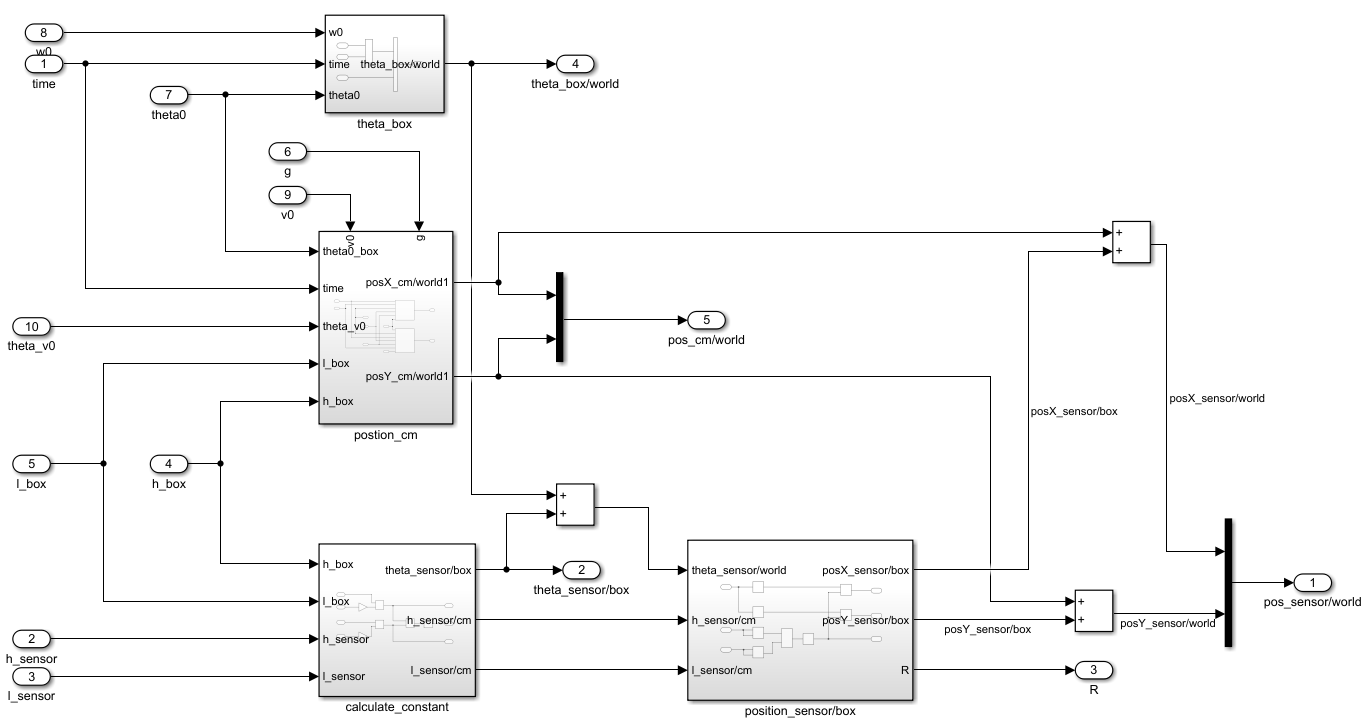

รูปที่ 4 การออกแบบระบบย่อย Plant

        สมการคำนวณหาทิศการหมุนของวัตถุเมื่อเทียบกับเฟรมโลก ($\theta_{s/w}$)

       
$$\theta_{b/w} \;\left(t\right)=\left(w_0 t\right)+\theta_0$$


       
$$\theta_{s/b} =\arctan \left(\frac{h_s -\frac{h_b }{2}}{l_s -\frac{l_b }{2}}\right)$$


        
$$\theta_{s/w} \left(t\right)=\theta_{b/w} \left(t\right)+\theta_{s/b}$$


       สมการคำนวณหาตำแหน่งของเซนเซอร์เมื่อเทียบกับเฟรมโลก ($p_{s/w}$)

       
$$R=\sqrt{{\left(l\right.}_s -\frac{l_b }{2}{\left.\right)}^2 +{\left(h\right.}_s -\frac{h_b }{2}{\left.\right)}^2 }$$


       
$$P_{s/b} \;\left(\theta_{s/w} \left(t\right)\right)=$$

$$\left\lbrack \begin{array}{c}
\textrm{Rcos}\left(\theta_{s/w} \left(t\right)\right)\\
\textrm{Rsin}\left(\theta_{s/w} \left(t\right)\right)
\end{array}\right\rbrack$$


       $P_{\textrm{cm}} \left(t\right)$ =$\left\lbrack \begin{array}{c}
v_0 \cos \left(\theta_{v_0 } \right)t\\
\left(v_0 \sin \left(\theta_{v_0 } \right)t\right)-\left(\frac{1}{2}{\textrm{gt}}^2 \right)
\end{array}\right\rbrack$+$\left\lbrack \begin{array}{cc}
\cos \left(\theta_0 \right) & -\sin \left(\theta_0 \right)\\
\sin \left(\theta_0 \right) & \cos \left(\theta_0 \right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\frac{l_b }{2}\\
\frac{h_b }{2}
\end{array}\right\rbrack$

       $P_{s/w}$($\theta_{s/w} \left(t\right),t$) = $P_{s/b} \;\left(\theta_{s/w} \left(t\right)\right)$+$P_{\textrm{cm}} \left(t\right)$

           โดยภายในระบบกายภาพจะประกอบด้วย 3 ระบบย่อย และ 1 กล่องคำนวณค่าคงที่ในระบบ ดังนี้

####                 1.1 theta_box subsystem

                    Input :    เวลา (time)

                    Output : มุมที่แกน $X_0$ ทำมุมกับแกน $X_M$ ในทิศ $\hat{k}$ ($\theta_{b/w}$)

        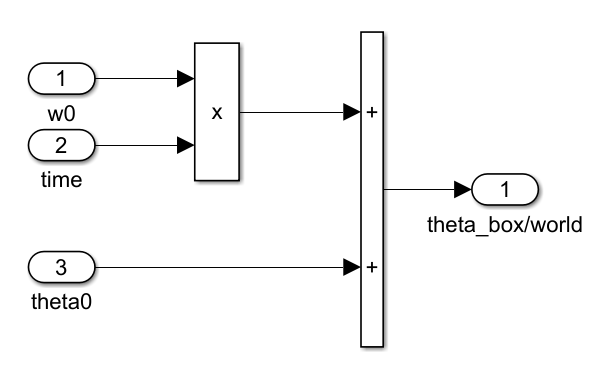

รูปที่ 5 การออกแบบระบบย่อย theta_box

####                  1.2 position_cm subsystem

                        Input :     เวลา (time)

                        Output : ตำแหน่งจุดศูนย์กลางมวลเมื่อเทียบกับเฟรมโลก ($p_{x,\textrm{cm}/w} \;\;,{\;p}_{y,\textrm{cm}/w}$)

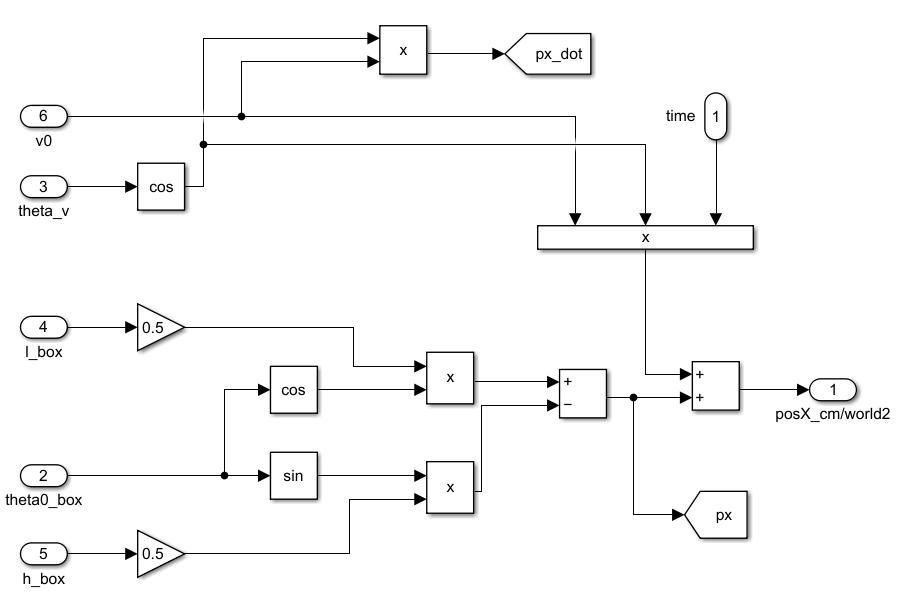

รูปที่ 6 การออกแบบระบบย่อย position_cm (แกน X)

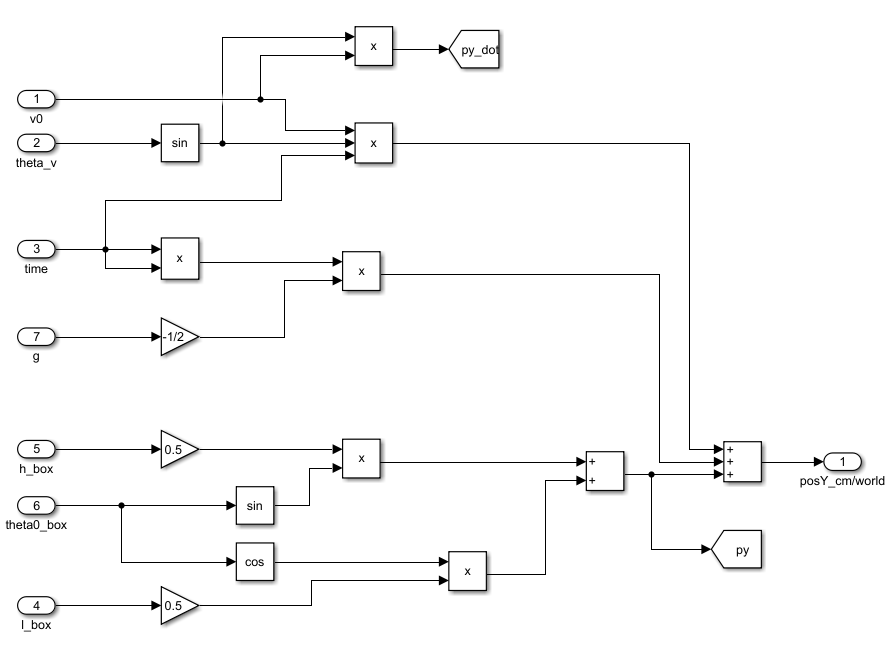

รูปที่ 7 การออกแบบระบบย่อย position_cm (แกน Y)

####                 1.3 position_sensor/box subsystem

                    Input :     มุมของ $\overset{\rightharpoonup }{\textrm{AB}}$ เมื่อเทียบกับแกน $X_0$ ในทิศ -$\hat{k}$ ($\theta_{\textrm{cm}-s/b}$)

                    Output : ระยะห่างระหว่างตำแหน่งของเซนเซอร์กับจุดศูนย์กลางมวลบนเฟรมโลก (${p_{x,s/b} \;,\;p}_{y,s/b}$) 

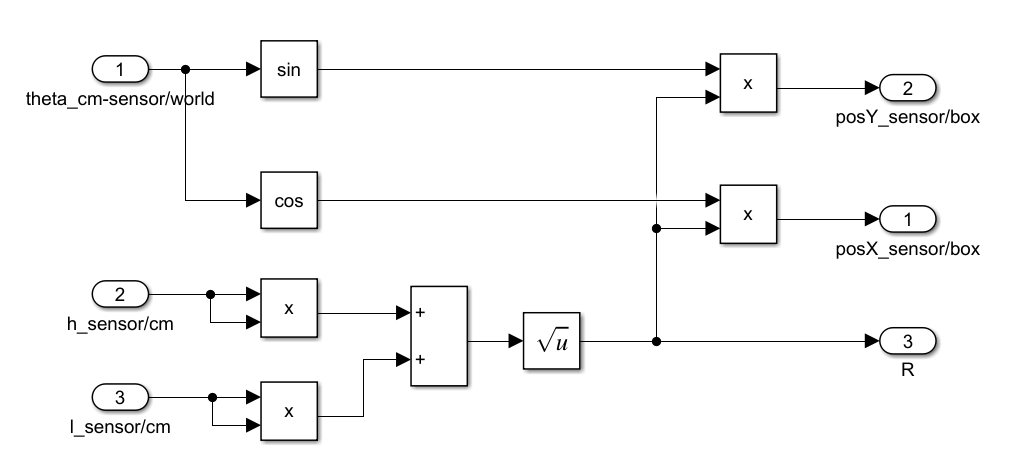

รูปที่ 8 การออกแบบระบบย่อย position_sensor/box

####                     1.4 calculate_constant box

                        คำนวณหา ระยะห่างระหว่างตำแหน่งเซนเซอร์กับจุดศูนย์กลางมวลบนเฟรมวัตถุ ($l_{s/\textrm{cm}} \;,h_{s/\textrm{cm}} \;$) และ มุมของ $\overset{\rightharpoonup }{\textrm{AB}}$ เมื่อเทียบกับแกน $X_M$ ในทิศ -$\hat{k}$ ($\theta_{s/b}$)

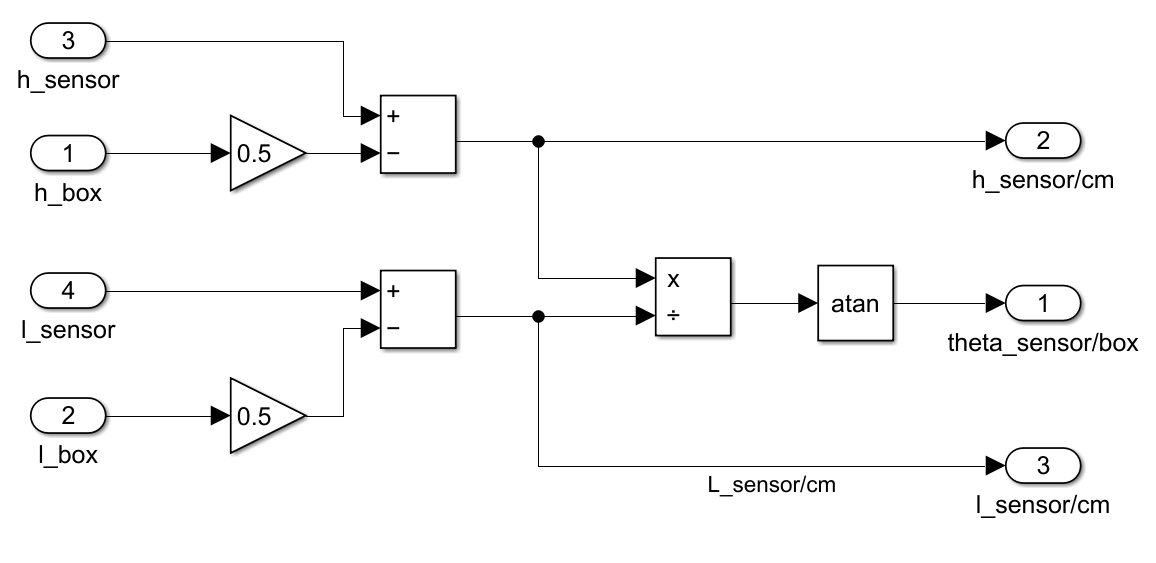

รูปที่ 9 การออกแบบกล่องคำนวณค่าคงที่

####         2. Sensor Subsystem

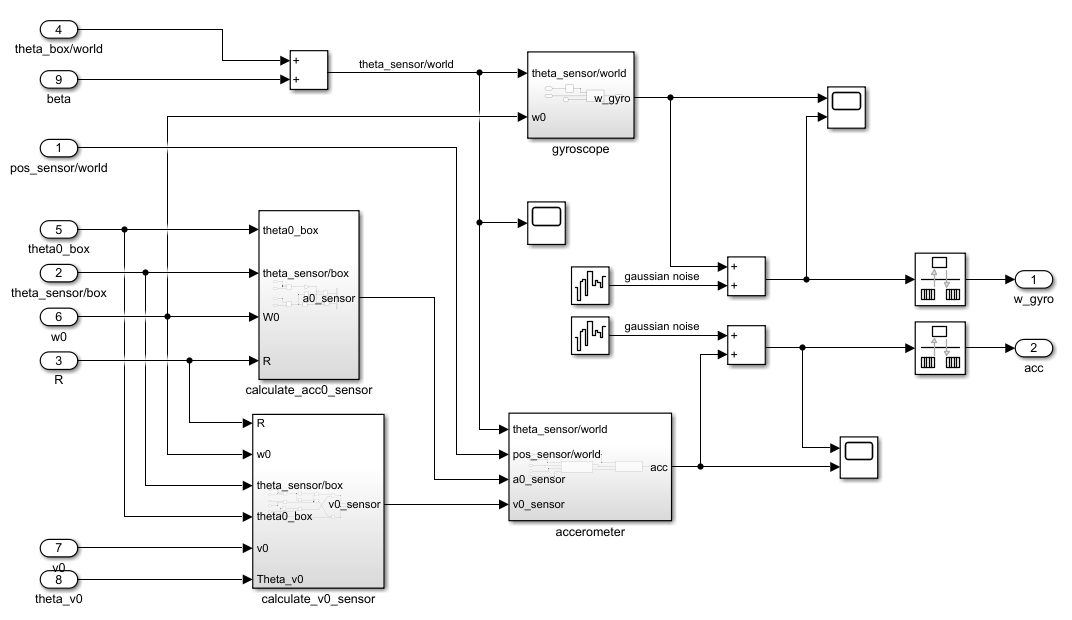

รูปที่ 10 การออกแบบระบบย่อย Sensor 

        สมการคำนวณค่าความเร็วเชิงมุมของเซนเซอร์ ($w_{\textrm{gyro}}$)

        
$$w_{\textrm{gyro}} =w_0 +G\left(0\ldotp 01\right)+\left(-w_0 +\frac{\mathrm{d}}{\mathrm{d}t}\theta \right)U\left(t\right)$$


        สมการคำนวณค่าความเร่งเชิงเส้นของเซนเซอร์ ($a_{\textrm{acc}}$)

        $v_0$=$\left\lbrack \begin{array}{c}
\left(v_0 \cos \left(\theta_{v_0 } \right)\right)+\left({\mathrm{w}}_0 \textrm{Rcos}\left(\frac{\textrm{pi}}{2}+\theta_{s/b} +\theta_0 \right)\right)\\
\left(v_0 \sin \left(\theta_{v_0 } \right)\right)+\left(w_0 \textrm{Rsin}\left(\frac{\textrm{pi}}{2}+\theta_{s/b} +\theta_0 \right)\right)
\end{array}\right\rbrack$

        $a_0$=$\left\lbrack \begin{array}{c}
-{\mathrm{w}}^2 \textrm{Rcos}\left(\theta_{s/b} +\theta_0 \right)\\
-g+\left(-{\mathrm{w}}^2 \textrm{Rsin}\left(\theta_{s/b} +\theta_0 \right)\right)
\end{array}\right\rbrack$

        
$$v\left(t\right)=v_0 +G\left(0\ldotp 01\right)+\left(-v_0 +\frac{d}{\mathrm{d}t}P_{s/w} \left(\theta_{s/w} \left(t\right),t\right)\right)U\left(t\right)$$


        
$$a\left(t\right)=a_0 -\left\lbrack \begin{array}{c}
0\\
-g
\end{array}\right\rbrack +G\left(0\ldotp 01\right)+\left(-a_0 +\frac{d}{\mathrm{d}t}v\left(t\right)\right)U\left(t\right)$$


        
$$a_{\textrm{acc}} =\left\lbrack \begin{array}{cc}
\cos \left(-\theta_{b/w} -\beta \right) & -\sin \left(-\theta_{b/w} -\beta \right)\\
\sin \left(-\theta_{b/w} -\beta \right) & \cos \left(-\theta_{b/w} -\beta \right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_x \left(t\right)\\
a_y \left(t\right)
\end{array}\right\rbrack$$


            โดยภายในระบบเซนเซอร์จะประกอบด้วย 2 ระบบย่อย และ 2 กล่องคำนวณค่าคงที่ในระบบ ดังนี้

####                 2.1 gyroscope subsystem

                    Input : มุมที่แกน $X_0$ ทำมุมกับแกน $X_I$ ในทิศ $\hat{k}$ ($\theta_{s/w}$)

                    Output : ความเร็วเชิงมุมของ Gyroscope ($w_{\textrm{gyro}}$)

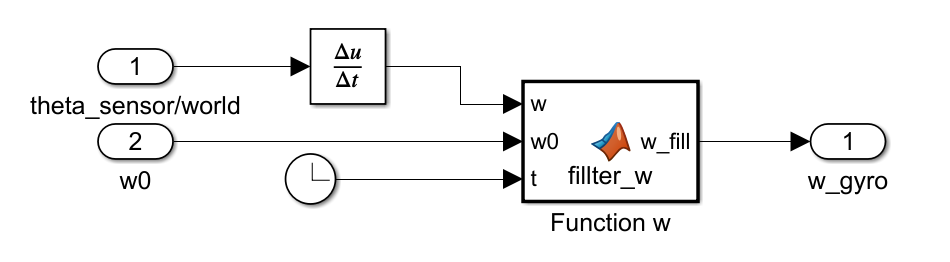

รูปที่ 11 การออกแบบระบบย่อย gyroscope

####                 2.2 accelerometer subsystem

                    Input :     มุมที่แกน $X_0$ ทำมุมกับแกน $X_I$ ในทิศ $\hat{k}$ ($\theta_{s/w}$) , ตำแหน่งของเซนเซอร์เมื่อเทียบกับเฟรมโลก ($p_{s/w}$) , ความเร่งเชิงเส้นของเซนเซอร์บนเฟรมโลกที่ตำแหน่งเริ่มต้น ($a_s$) และ ความเร็วเชิงเส้นของเซนเซอร์บนเฟรมโลกที่ตำแหน่งเริ่มต้น ($v_{0,s}$)

                    Output : เวกเตอร์ความเร่งของเซนเซอร์บนเฟรมเซนเซอร์ ($a_{\textrm{acc}}$)

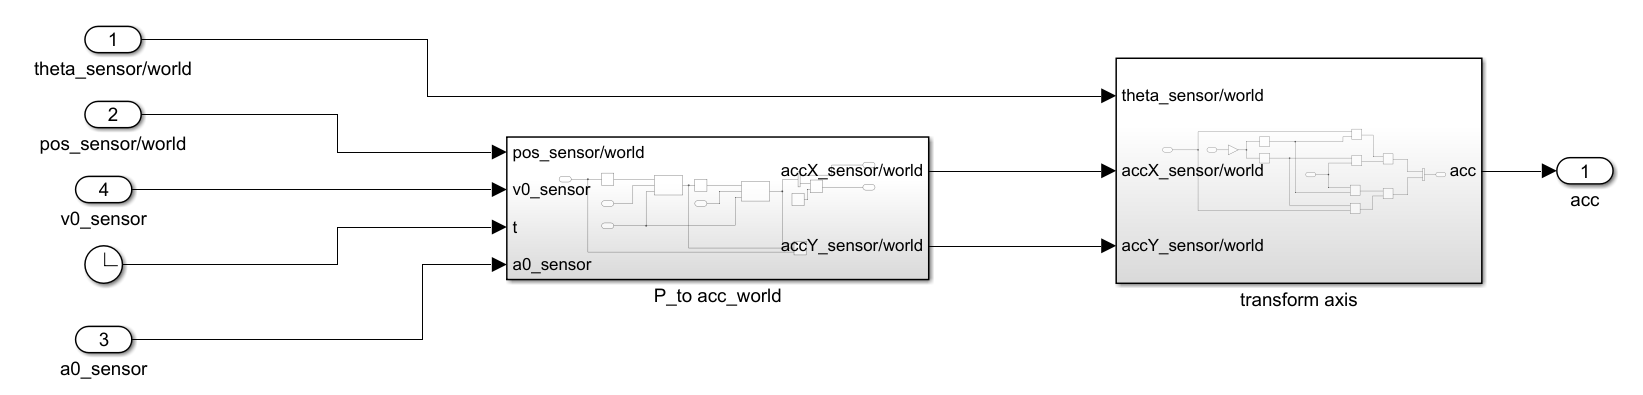

รูปที่ 12 การออกแบบระบบย่อย accelerometer

                    โดยประกอบด้วย 2 ระบบ ดังนี้

                    P_to acc_world : ระบบคำนวณหาอนุพันธ์อันดับที่ 2 ของตำแหน่งเซนเซอร์เมื่อเทียบกับเฟรมโลก ($p_{s/w}$)

                    transform axis : ระบบเปลี่ยนความเร่งเชิงเส้นของเซนเซอร์บนเฟรมโลก (${\textrm{acc}}_{s/w}$) ให้อยู่บนเฟรมของเซนเซอร์

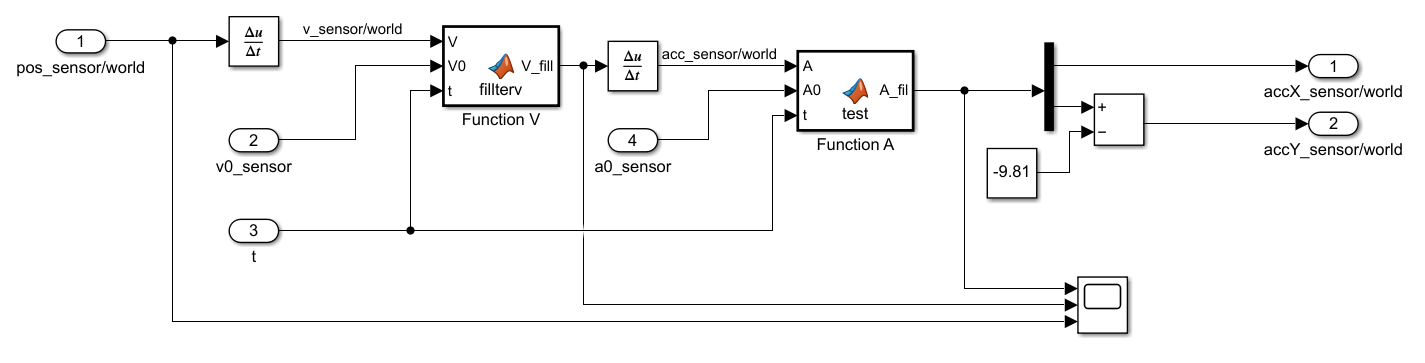

รูปที่ 13 การออกแบบระบบ P_to acc_world

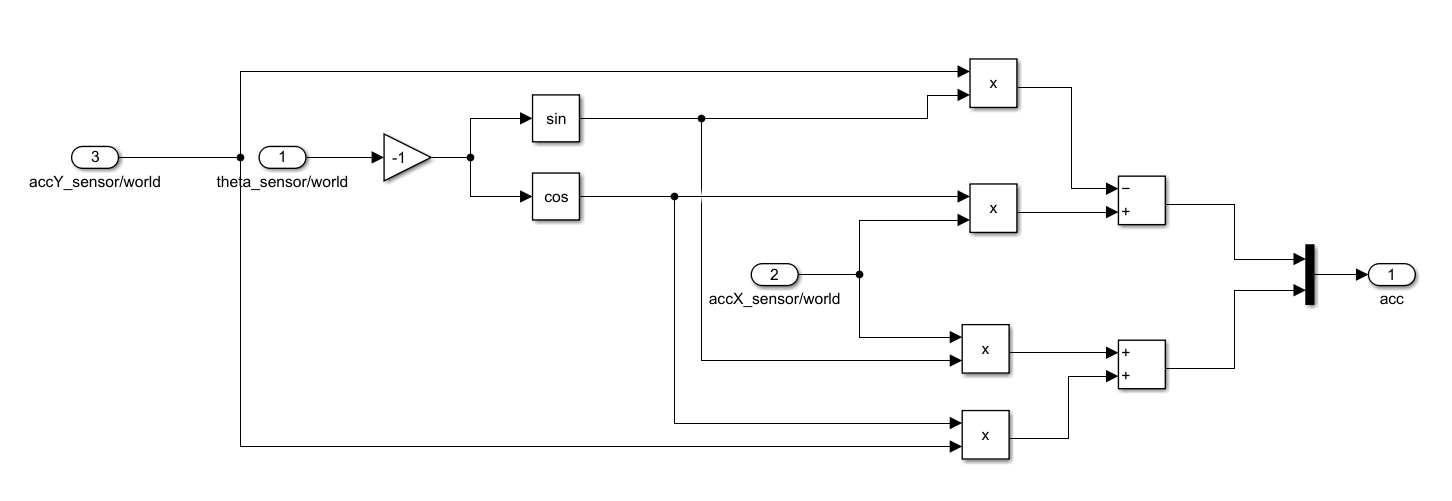

รูปที่ 14 การออกแบบระบบ transform axis

####                 2.3 calculate_acc0_sensor box

                    คำนวณหา ความเร่งเชิงเส้นของเซนเซอร์บนเฟรมโลกที่ตำแหน่งเริ่มต้น ($a_s$)

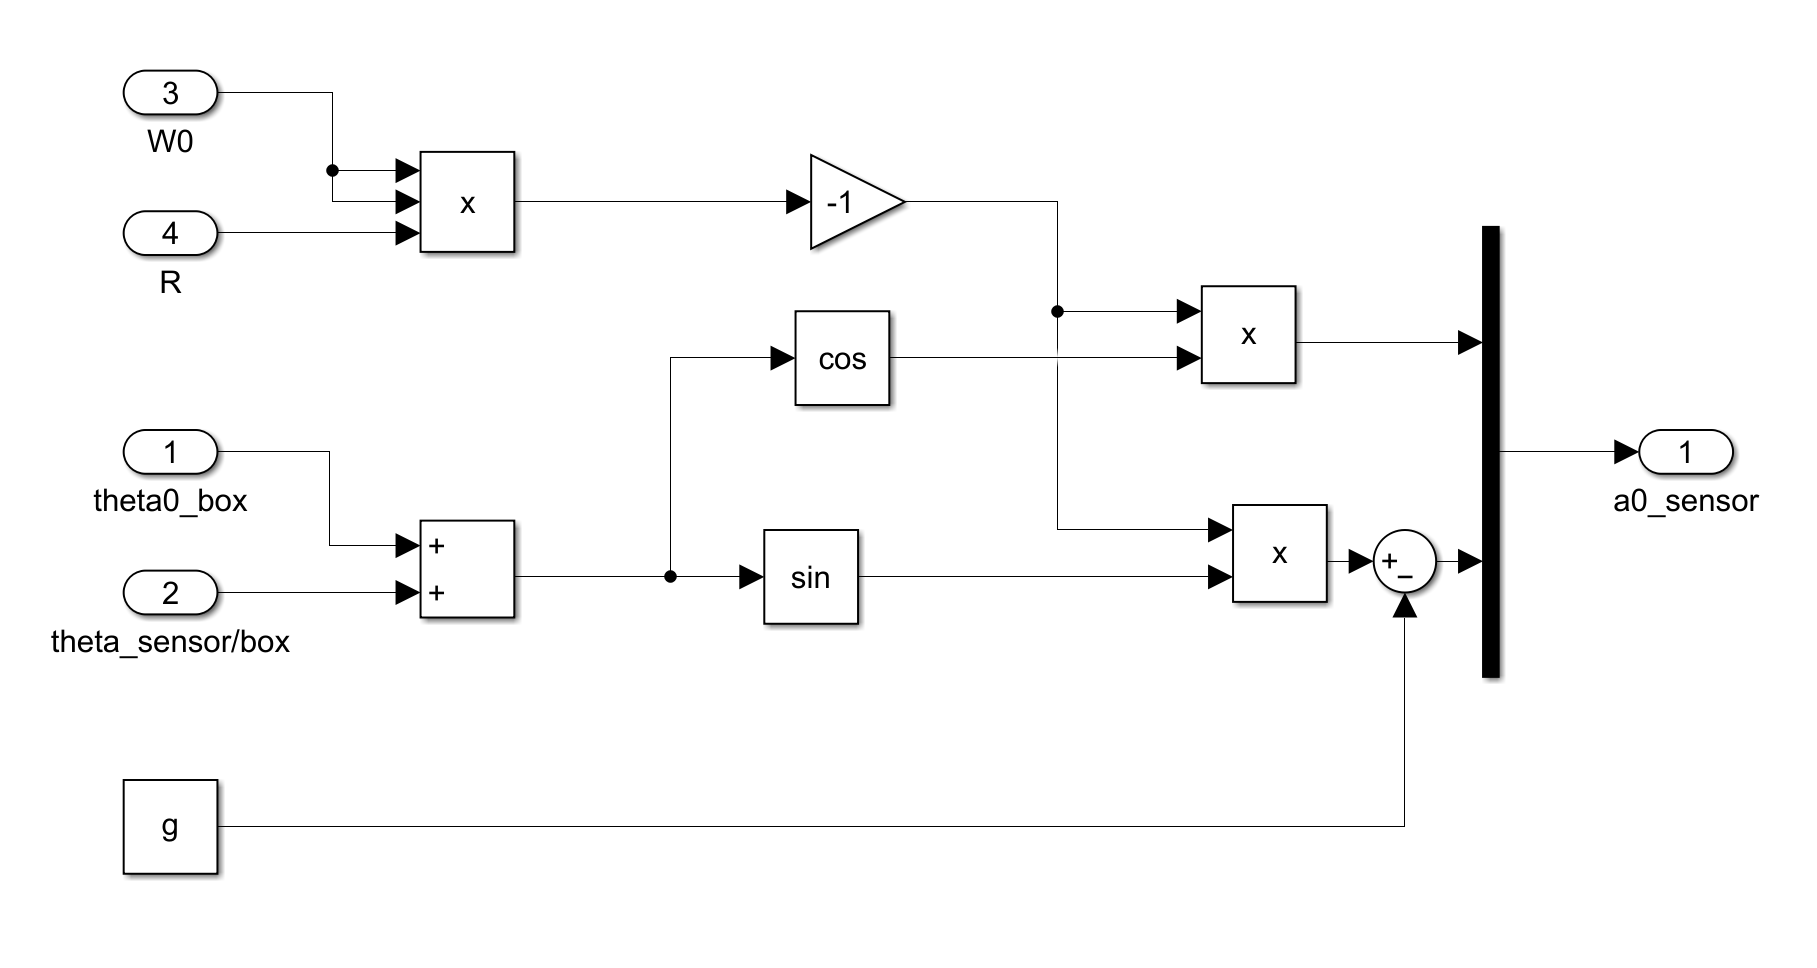

รูปที่ 15 การออกแบบกล่องคำนวณความเร่งเชิงเส้นของเซนเซอร์

####                 2.4 calculate_v0_sensor box

                    คำนวณหา ความเร็วเชิงเส้นของเซนเซอร์บนเฟรมโลกที่ตำแหน่งเริ่มต้น ($v_s$)

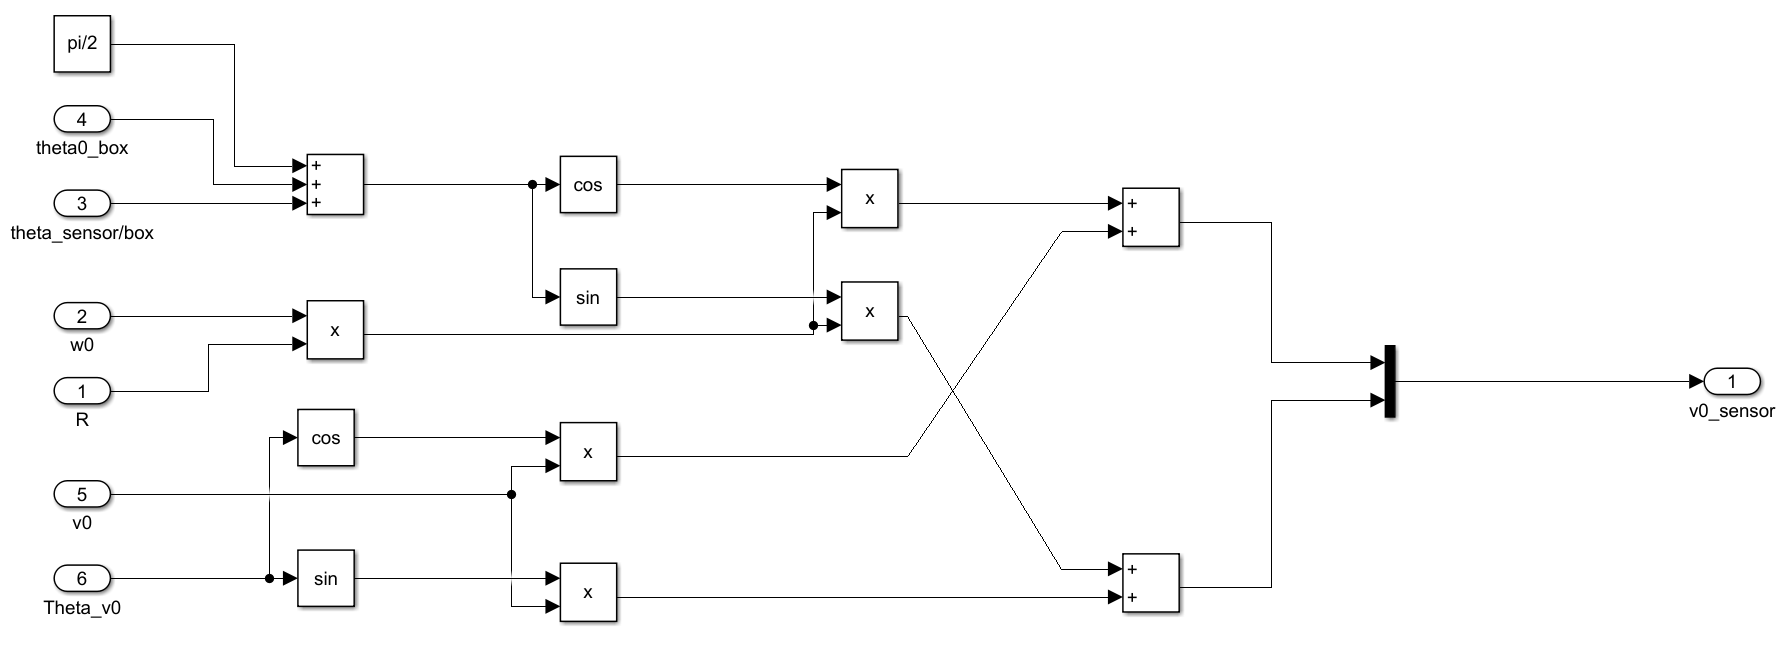

รูปที่ 16 การออกแบบกล่องคำนวณความเร็วเชิงเส้นของเซนเซอร์

#### **        3. **Time-Invariant Kalman Filter Subsystem

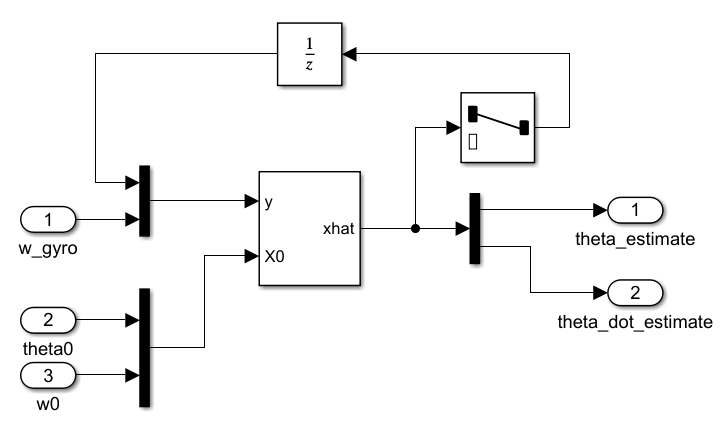

รูปที่ 17 การออกแบบระบบย่อย Time-Invariant Kalman Filter

        Subsystem ที่ใช้ในการประมาณค่ามุมที่วัตถุหมุนโดยมี Input เป็นค่าความเร็วเชิงมุมที่ได้จาก gyroscope ใน Sensor Subsystem และให้ Output เป็นมุมและความเร็วเชิงมุมที่ได้จากการประมาณค่าโดย Time-Invariant Kalman Filter (theta_estimate และ theta_dot_estimate)

        โดยเรามีสมการ Process model และ Measurement model ดังนี้

        
$$\overset{\rightharpoonup }{x} \left\lbrack k+1\right\rbrack =\left\lbrack \begin{array}{c}
\theta \left\lbrack k+1\right\rbrack \\
\dot{\theta} \left\lbrack k+1\right\rbrack 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & \Delta t\\
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\theta \left\lbrack k\right\rbrack \\
\dot{\theta} \left\lbrack k\right\rbrack 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\frac{1}{2}{\Delta t}^2 \\
\Delta t
\end{array}\right\rbrack w\left\lbrack k\right\rbrack$$


        
$$\overset{\rightharpoonup }{y_g } \left\lbrack k\right\rbrack =\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\theta \left\lbrack k\right\rbrack \\
\dot{\theta} \left\lbrack k\right\rbrack 
\end{array}\right\rbrack +v\left\lbrack k\right\rbrack$$


        ดังนั้นเราจึงได้สัมประสิทธิ์ 

        A = $\left\lbrack \begin{array}{cc}
1 & \Delta t\\
0 & 1
\end{array}\right\rbrack$

        C = $\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$

        G = $\left\lbrack \begin{array}{c}
\frac{1}{2}{\Delta t}^2 \\
\Delta t
\end{array}\right\rbrack$

        ค่า Covariance ของ Measurement Noise (R_I) คือ 0.01 ตาม ω~N(0,0.01) ของเซนเซอร์ gyroscopce

        ค่า Covariance ของ Process Noise (Q_I) ใช้เป็น 0.0000001 เนื่องจากการจำลองระบบไม่มี Process Noise แต่ไม่สามารถใส่ค่า 0 ได้จึงใช้ค่าที่น้อยแทน

####         4.Time-Variant Kalman Filter Subsystem

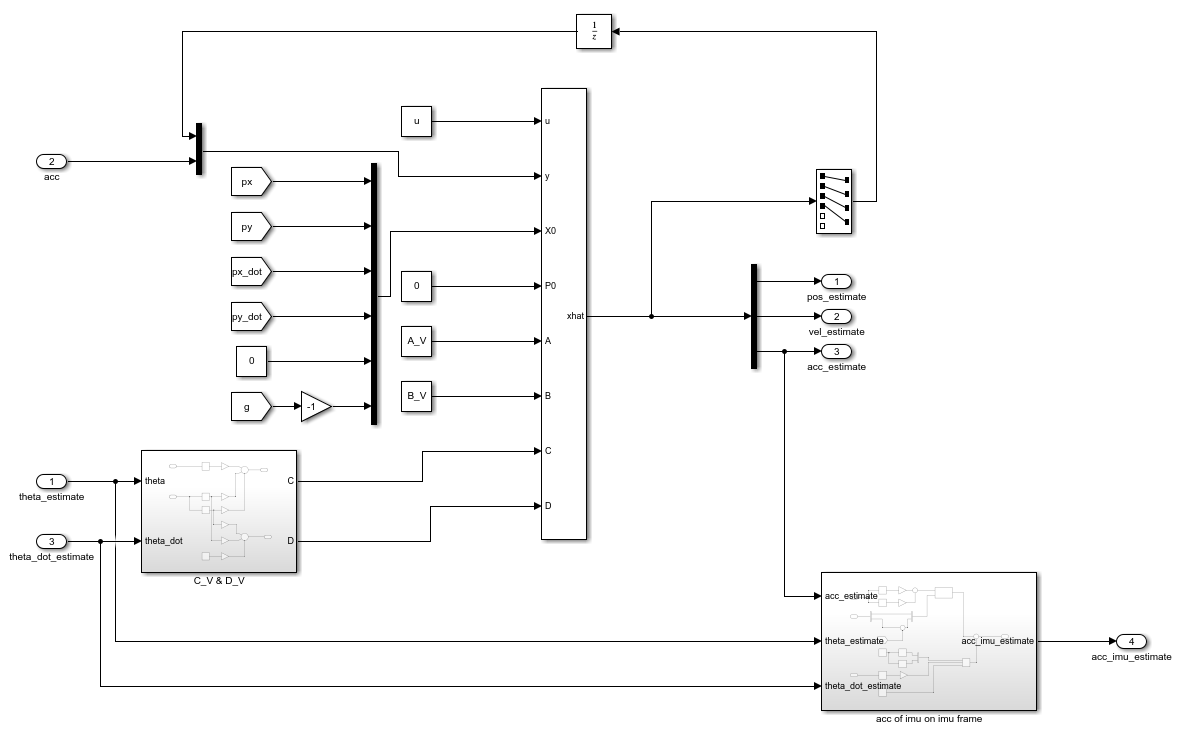

รูปที่ 18 การออกแบบระบบย่อย Time-Variant Kalman Filter

        Subsystem ที่ใช้ในการประมาณค่าตำแหน่ง, ความเร็ว และความเร่งของวัตถุเมื่อเทียบกับเฟรมโลก โดยมี Input เป็นค่ามุมและความเร็วเชิงมุมที่ได้จากการประมาณค่าโดย Time-Invariant Kalman Filter Subsystem และความเร่งที่ได้จาก accelerometer ใน Sensor Subsystem และให้ Output เป็นค่าตำแหน่ง, ความเร็ว และความเร่งของจุดศูนย์กลางมวลเมื่อเทียบกับเฟรมโลกที่ได้จากการประมาณค่าโดย Time-Variant Kalman Filter (pos_estimate, vel_estimate และ acc_estimate)

        โดยเรามีสมการ Process model และ Measurement model ดังนี้

        
$$\overset{\rightharpoonup }{x} \left\lbrack k+1\right\rbrack =\left\lbrack \begin{array}{c}
p_x \left\lbrack k+1\right\rbrack \\
p_y \left\lbrack k+1\right\rbrack \\
{\dot{p} }_x \left\lbrack k+1\right\rbrack \\
{\dot{p} }_y \left\lbrack k+1\right\rbrack \\
{\ddot{p} }_x \left\lbrack k+1\right\rbrack \\
{\ddot{p} }_y \left\lbrack k+1\right\rbrack 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
1 & 0 & \Delta t & 0 & 0 & 0\\
0 & 1 & 0 & \Delta t & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0\\
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
p_x \left\lbrack k\right\rbrack \\
p_y \left\lbrack k\right\rbrack \\
{\dot{p} }_x \left\lbrack k\right\rbrack \\
{\dot{p} }_y \left\lbrack k\right\rbrack \\
{\ddot{p} }_x \left\lbrack k\right\rbrack \\
{\ddot{p} }_y \left\lbrack k\right\rbrack 
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
\frac{1}{2}{\Delta t}^2  & 0 & 0\\
0 & 0 & 0\\
\Delta t & 0 & 0\\
0 & 0 & 0\\
1 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
-g\\
\textrm{Rcos}\gamma \\
\textrm{Rsin}\gamma 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
\frac{1}{2}{\Delta t}^2  & 0\\
0 & \frac{1}{2}{\Delta t}^2 \\
\Delta t & 0\\
0 & \Delta t\\
1 & 0\\
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
w_x \left\lbrack k\right\rbrack \\
w_y \left\lbrack k\right\rbrack 
\end{array}\right\rbrack$$


        
$$\overset{\rightharpoonup }{y_a } \left\lbrack k\right\rbrack =\left\lbrack \begin{array}{cccccc}
1 & 0 & 0 & 0 & 0 & 0\\
0 & 1 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0\\
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & \cos \theta  & \sin \theta \\
0 & 0 & 0 & 0 & -\sin \theta  & \cos \theta 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
p_x \left\lbrack k\right\rbrack \\
p_y \left\lbrack k\right\rbrack \\
{\dot{p} }_x \left\lbrack k\right\rbrack \\
{\dot{p} }_y \left\lbrack k\right\rbrack \\
{\ddot{p} }_x \left\lbrack k\right\rbrack \\
{\ddot{p} }_y \left\lbrack k\right\rbrack 
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 0\\
\sin \theta  & -{\dot{\theta} }^2  & 0\\
\cos \theta  & 0 & {\dot{\theta} }^2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
-g\\
\textrm{Rcos}\gamma \\
\textrm{Rsin}\gamma 
\end{array}\right\rbrack +v\left\lbrack k\right\rbrack$$


        ดังนั้นเราจึงได้สัมประสิทธิ์

        A =$\left\lbrack \begin{array}{cccccc}
1 & 0 & \Delta t & 0 & 0 & 0\\
0 & 1 & 0 & \Delta t & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0\\
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack$

        B =$\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
\frac{1}{2}{\Delta t}^2  & 0 & 0\\
0 & 0 & 0\\
\Delta t & 0 & 0\\
0 & 0 & 0\\
1 & 0 & 0
\end{array}\right\rbrack$

        C =$\left\lbrack \begin{array}{cccccc}
1 & 0 & 0 & 0 & 0 & 0\\
0 & 1 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0\\
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & \cos \theta  & \sin \theta \\
0 & 0 & 0 & 0 & -\sin \theta  & \cos \theta 
\end{array}\right\rbrack$

        D =$\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 0\\
\sin \theta  & -{\dot{\theta} }^2  & 0\\
\cos \theta  & 0 & {\dot{\theta} }^2 
\end{array}\right\rbrack$

        G =$\left\lbrack \begin{array}{cc}
\frac{1}{2}{\Delta t}^2  & 0\\
0 & \frac{1}{2}{\Delta t}^2 \\
\Delta t & 0\\
0 & \Delta t\\
1 & 0\\
0 & 1
\end{array}\right\rbrack$

        ค่า Covariance ของ Measurement Noise (R_I) คือ 0.01 ตาม f~N(0,0.01) ของเซนเซอร์ accelerometer

        ค่า Covariance ของ Process Noise (Q_I) ใช้เป็น $\left\lbrack \begin{array}{c}
0\ldotp 0000001\\
0\ldotp 0000001
\end{array}\right\rbrack$ เนื่องจากการจำลองระบบไม่มี Process Noise แต่ไม่สามารถใส่ค่า 0 ได้จึงใช้ค่าที่น้อยแทน

####        5. Error Validation Subsystem

        Subsystem ที่ใช้สำหรับนำค่าที่ได้จาก Plant Subsystem, Sensor Subsystem, Time-Invariant Kalman Filter Subsystem และ Time-Variant Kalman Filter Subsystem ออกมาสู่ Workspace เพื่อนำไปวิเคราะห์ผล และมีการหาค่าผลต่างของตำแหน่งและมุมที่ได้จาก Plant Subsystem กับค่าที่ได้จากการประมาณจาก Kalman Filter

        โดยมีค่าที่นำออกมาดังนี้

            - pos_cm/world

            - pos_estimate

            - acc

            - acc_imu_estimate

            - theta_box/world

            - theta_estimate

            - w_gyro

            - theta_dot_estimate

## 4. วิเคราะห์และสรุปผลการจำลอง

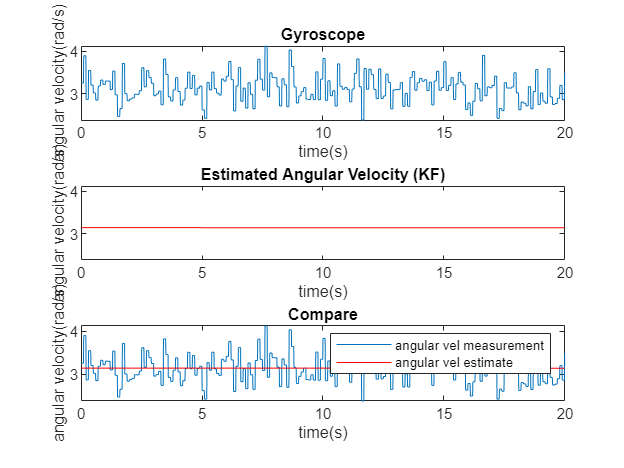

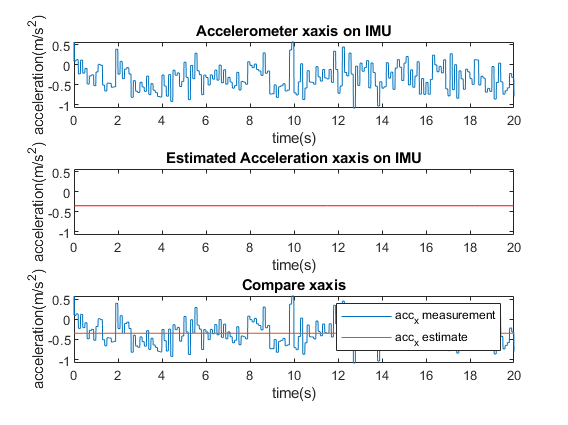

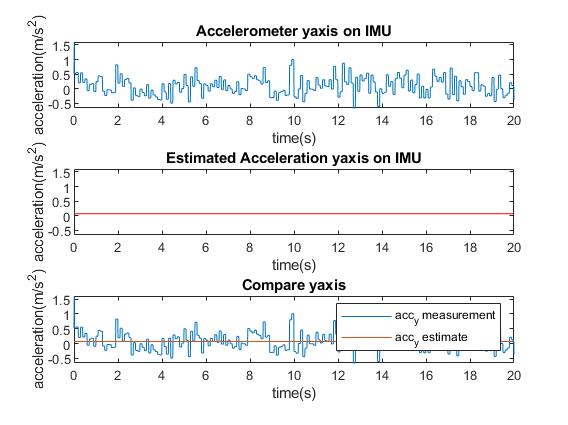

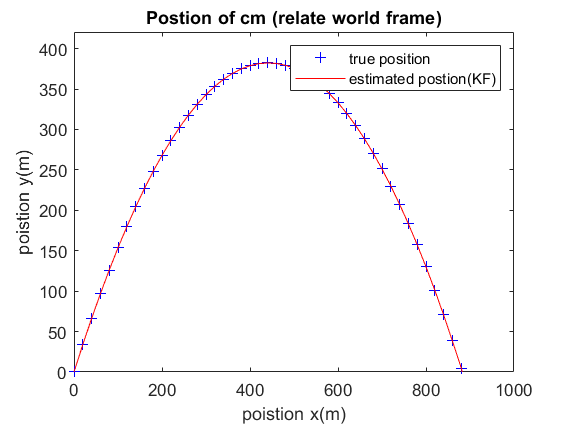

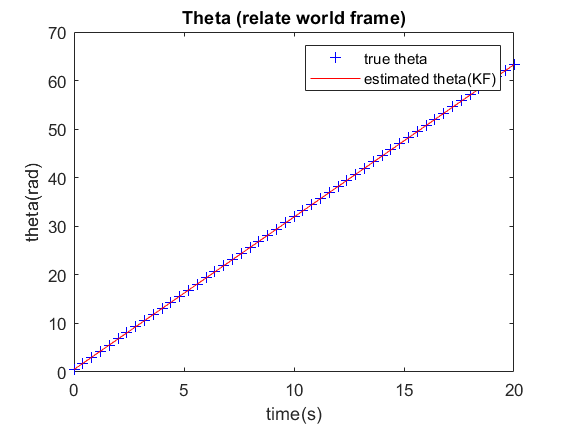

run('run_script.m'); % เรียกใช้งาน model simulink และนำค่าที่ได้มา plot กราฟแสดงผล โดยรันไฟล์ชื่อ 'run_script.m'

###         4.1 เปรียบเทียบสัญญาณจาก Gyroscope กับสัญญาณที่ถูกกรอง

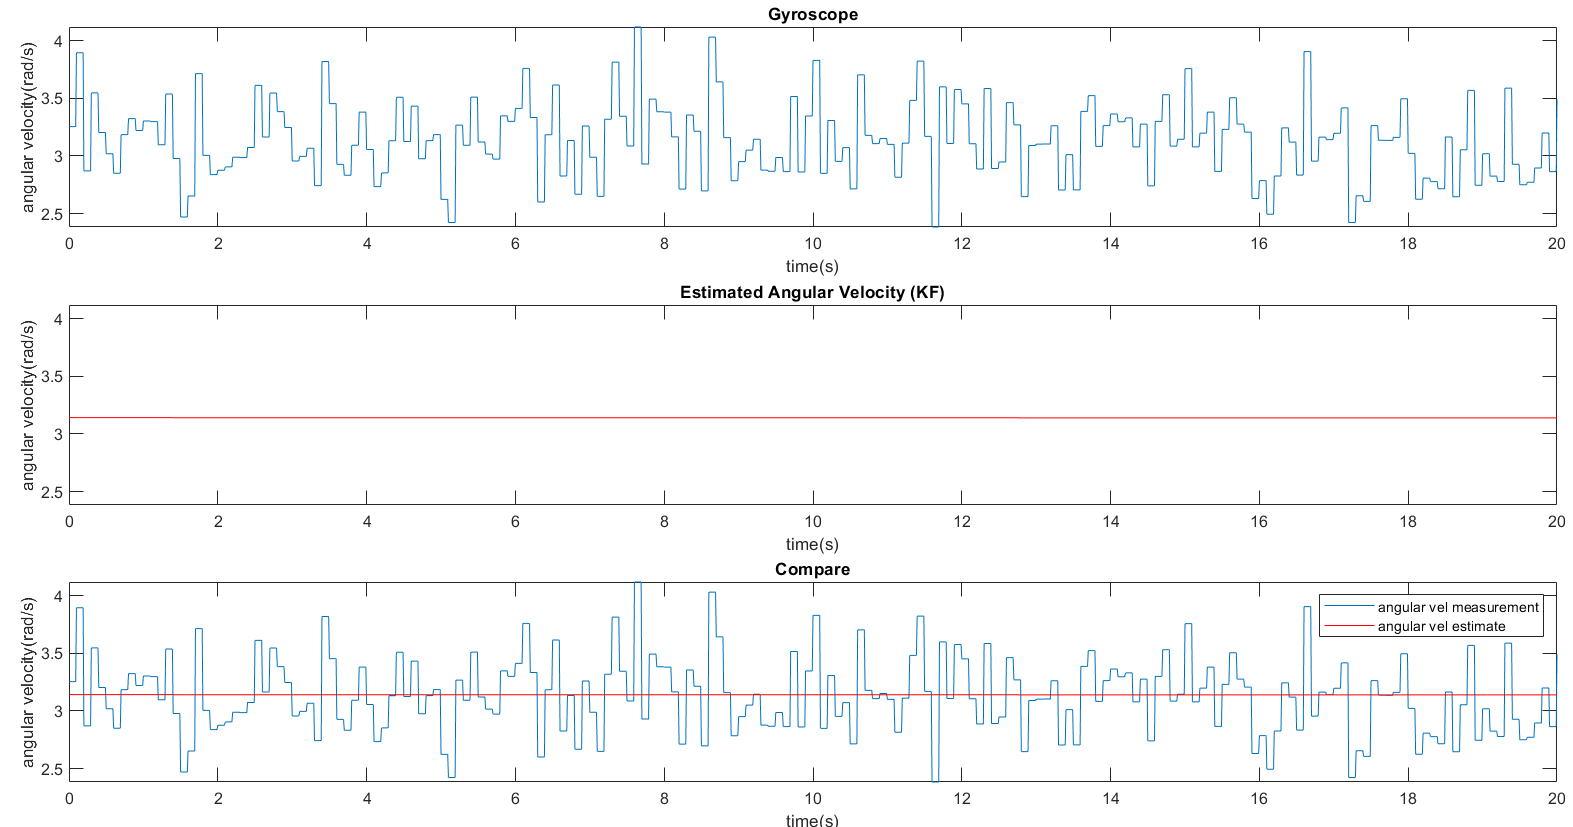

รูปที่ 19 กราฟเปรียบเทียบสัญญาณจาก Gyroscope กับสัญญาณที่ถูกกรอง

                จากกราฟจะเห็นได้ว่าสัญญาณที่ได้จาก Gyroscope จะมี Measurement Noise ทำให้สัญญาณไม่เรียบ แต่หลังจากผ่าน Kalman Filter สัญญาณที่ได้มีลักษณะคงที่และมีค่าอยู่ขอบเขตใกล้เคียงกับค่าความเร็วเชิงมุมที่ Plant Subsystem ซึ่งกำหนดอยู่ที่ 3.1416 rad/s

###         4.2 เปรียบเทียบสัญญาณจาก Accelerometer กับสัญญาณที่ถูกกรอง

####                 1. สัญญาณในแกน X

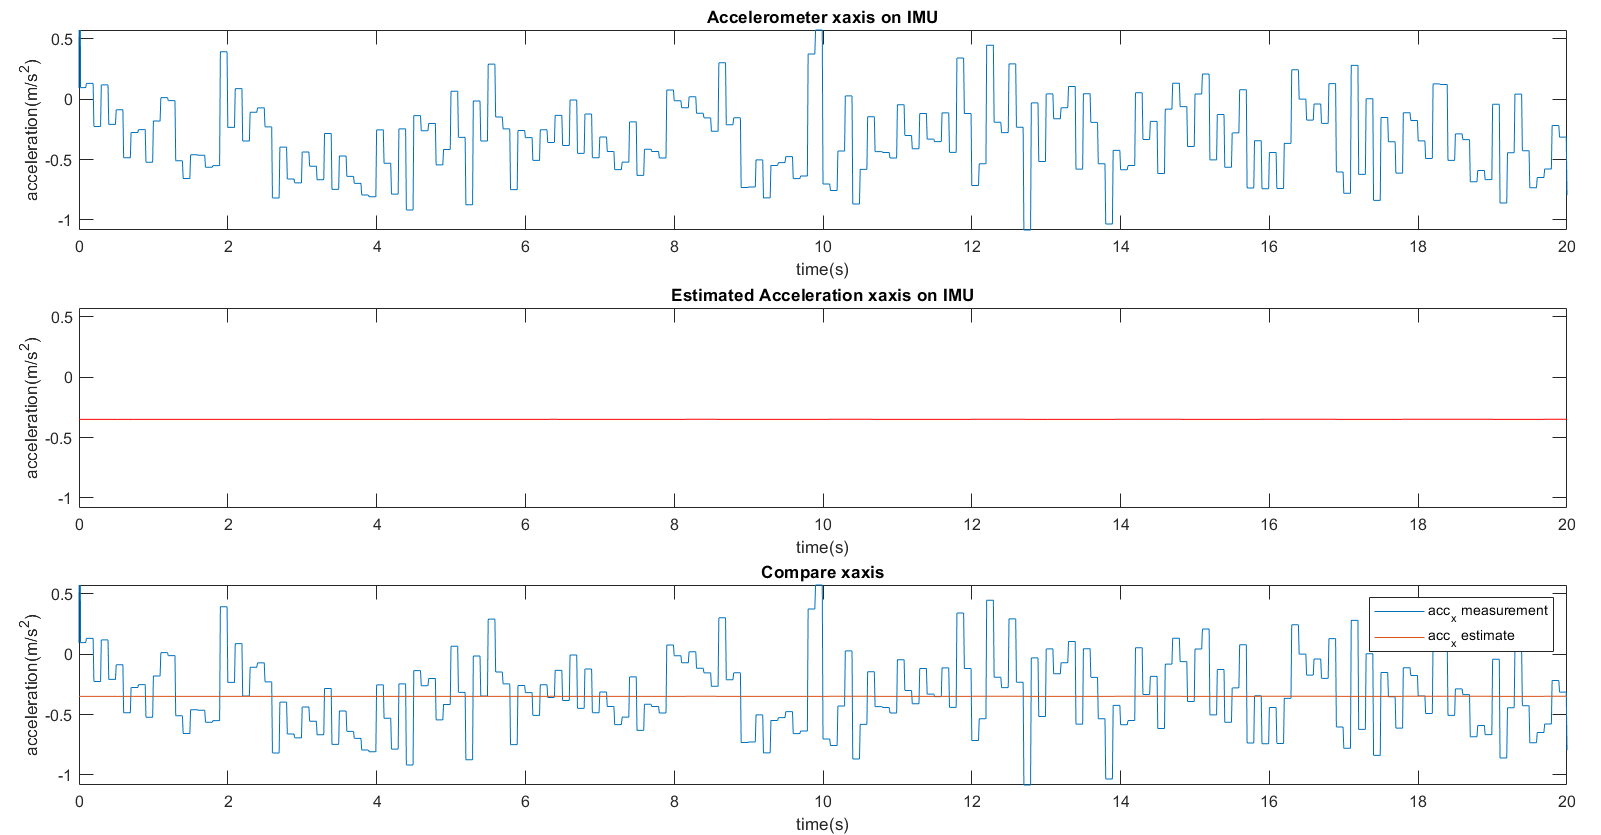

รูปที่ 20 เปรียบเทียบสัญญาณจาก Accelerometer กับสัญญาณที่ถูกกรอง ในแกน X

                จากกราฟจะเห็นได้ว่าสัญญาณที่ได้จาก Accelerometer จะมี Measurement Noise ทำให้สัญญาณไม่เรียบ แต่หลังจากผ่าน Kalman Filter สัญญาณที่ได้มีลักษณะที่เรียบขึ้นและมีค่าอยู่ในช่วงของสัญญาณจาก Accelerometer

####                 2. สัญญาณในแกน Y

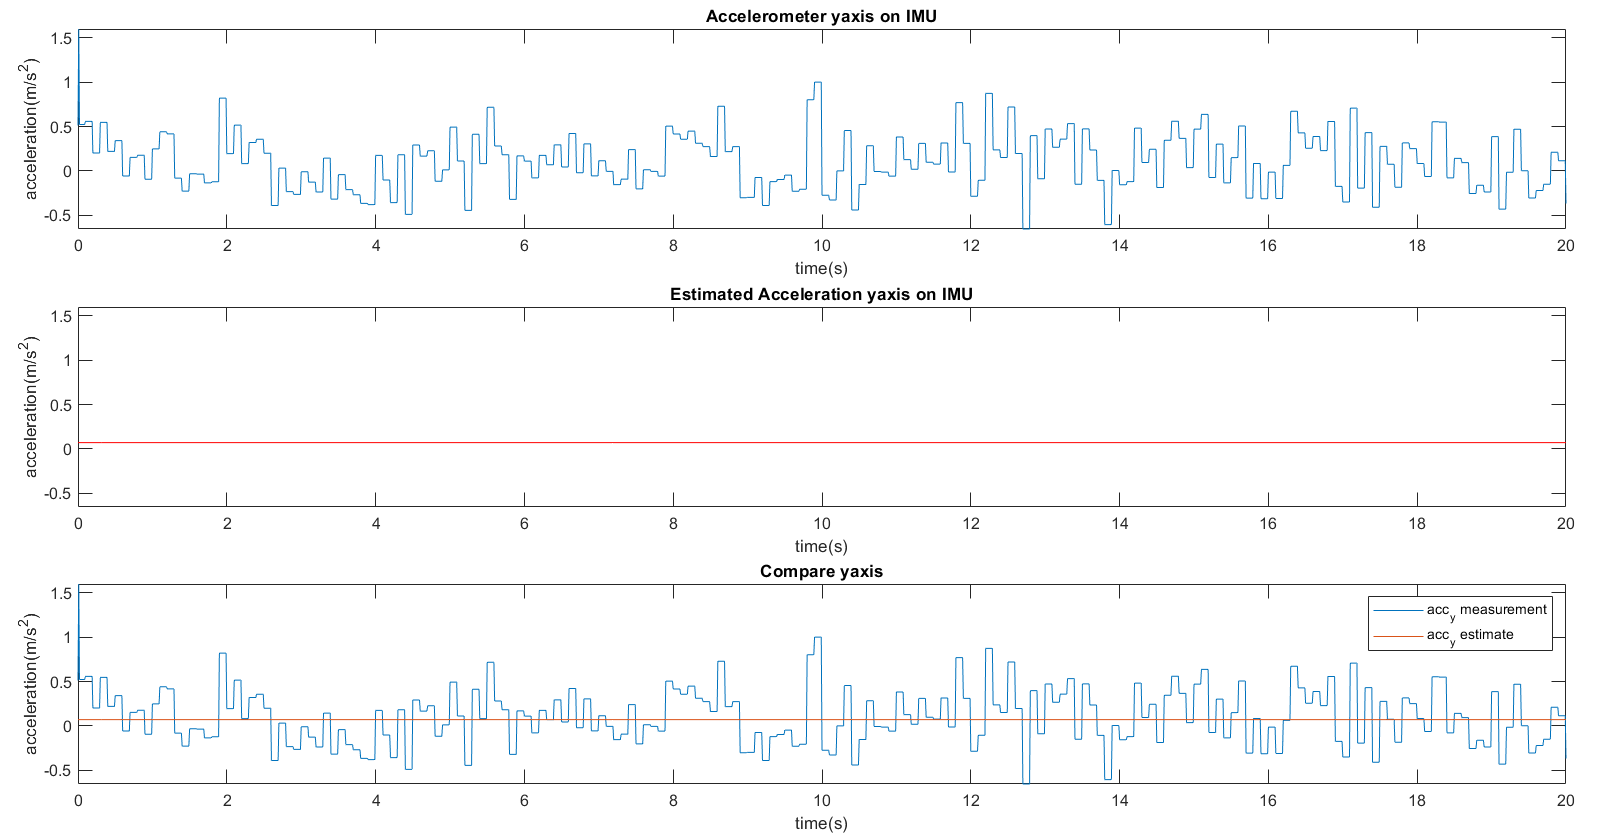

รูปที่ 21 เปรียบเทียบสัญญาณจาก Accelerometer กับสัญญาณที่ถูกกรอง ในแกน Y

                จากกราฟจะเห็นได้ว่าสัญญาณที่ได้จาก Accelerometer จะมี Measurement Noise ทำให้สัญญาณไม่เรียบ แต่หลังจากผ่าน Kalman Filter สัญญาณที่ได้มีลักษณะที่เรียบขึ้นและมีค่าอยู่ในช่วงของสัญญาณจาก Accelerometer

###         4.3 เปรียบเทียบตำแหน่งของจุดศูนย์กลางมวลของวัตถุบนเฟรมโลกค่าจริงกับค่าที่ประมาณได้

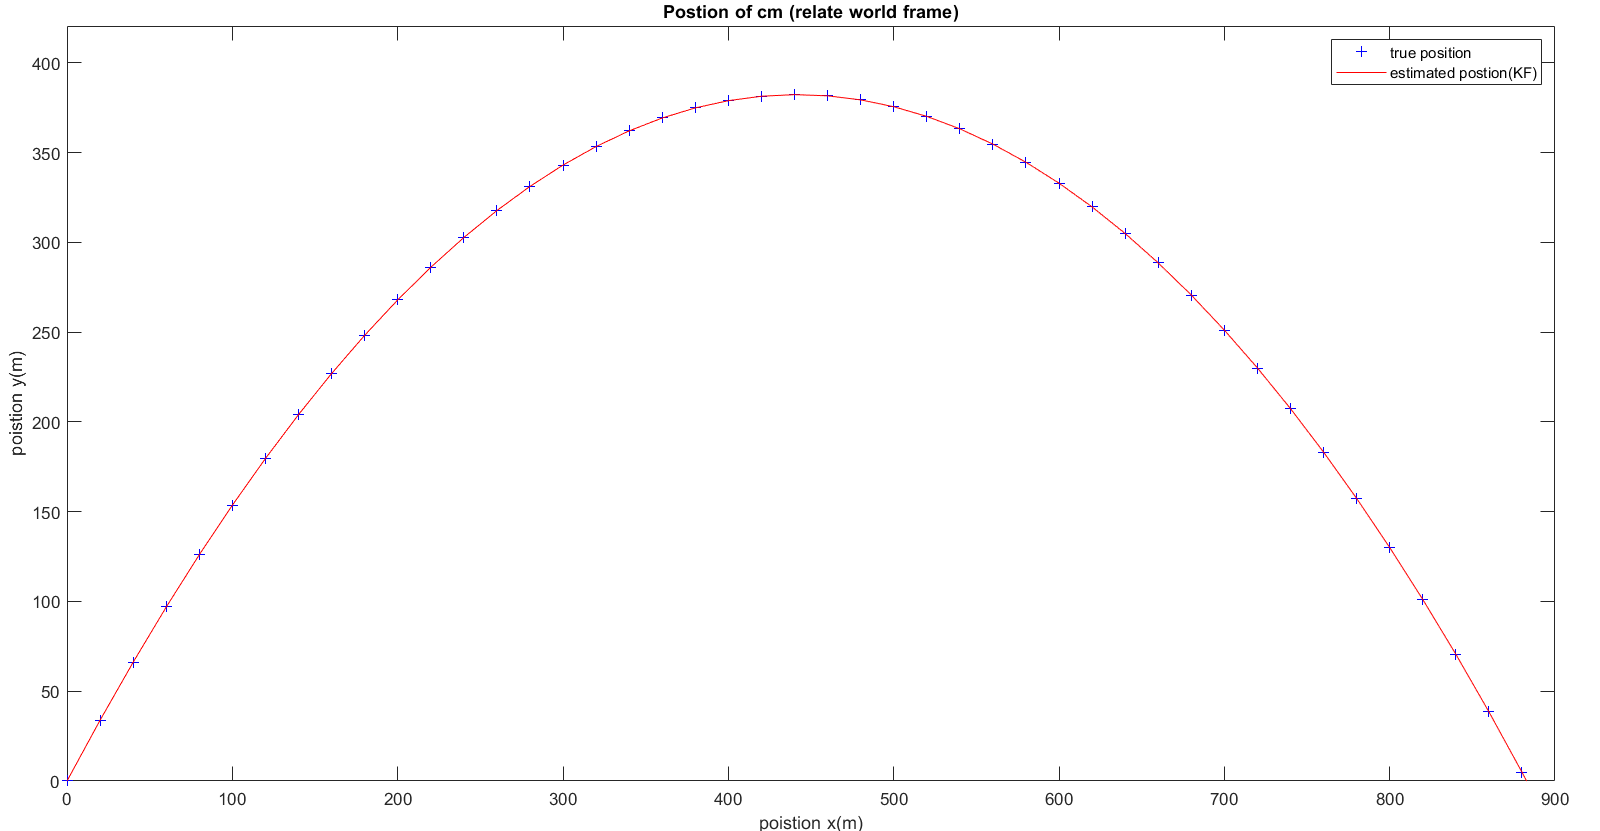

รูปที่ 22 กราฟเปรียบเทียบตำแหน่งของจุดศูนย์กลางมวลของวัตถุบนเฟรมโลกค่าจริงกับค่าที่ประมาณได้

(หมายเหตุ : กราฟจบที่ t = 17.65 s เนื่องจากต้องการให้ pos_y >= 0)

                จากกราฟจะเห็นได้ว่าตำแหน่งของจุดศูนย์กลางมวลของวัตถุบนเฟรมโลกที่จากการประมาณค่าผ่าน Kalman Filter มีค่าใกล้เคียงกับค่าจริง

และมีค่าเฉลี่ยของผลต่างระหว่างค่าที่ประมาณได้กับค่าจริงอยู่ที่

pos_x_error = mean(out.pos_error.Data(:,1))

pos_x_error = -0.0195

pos_y_error = mean(out.pos_error.Data(:,2))

pos_y_error = 0.0264

`pos_x_error = -0.0195 m`

`pos_y_error = 0.0264 m`

`ซึ่งจะเห็นได้ว่าความคลาดเคลื่อนที่ได้นั้นค่อนข้างน้อยแสดงว่าระบบการประมาณค่าของ Kalman Filter นั้นสามารถใช้งานได้`

### `    4.4 เปรียบเทียบม`ุมที่วัตถุเอียงเมื่อเทียบกับเฟรมโลกค่าจริงกับค่าที่ประมาณได้

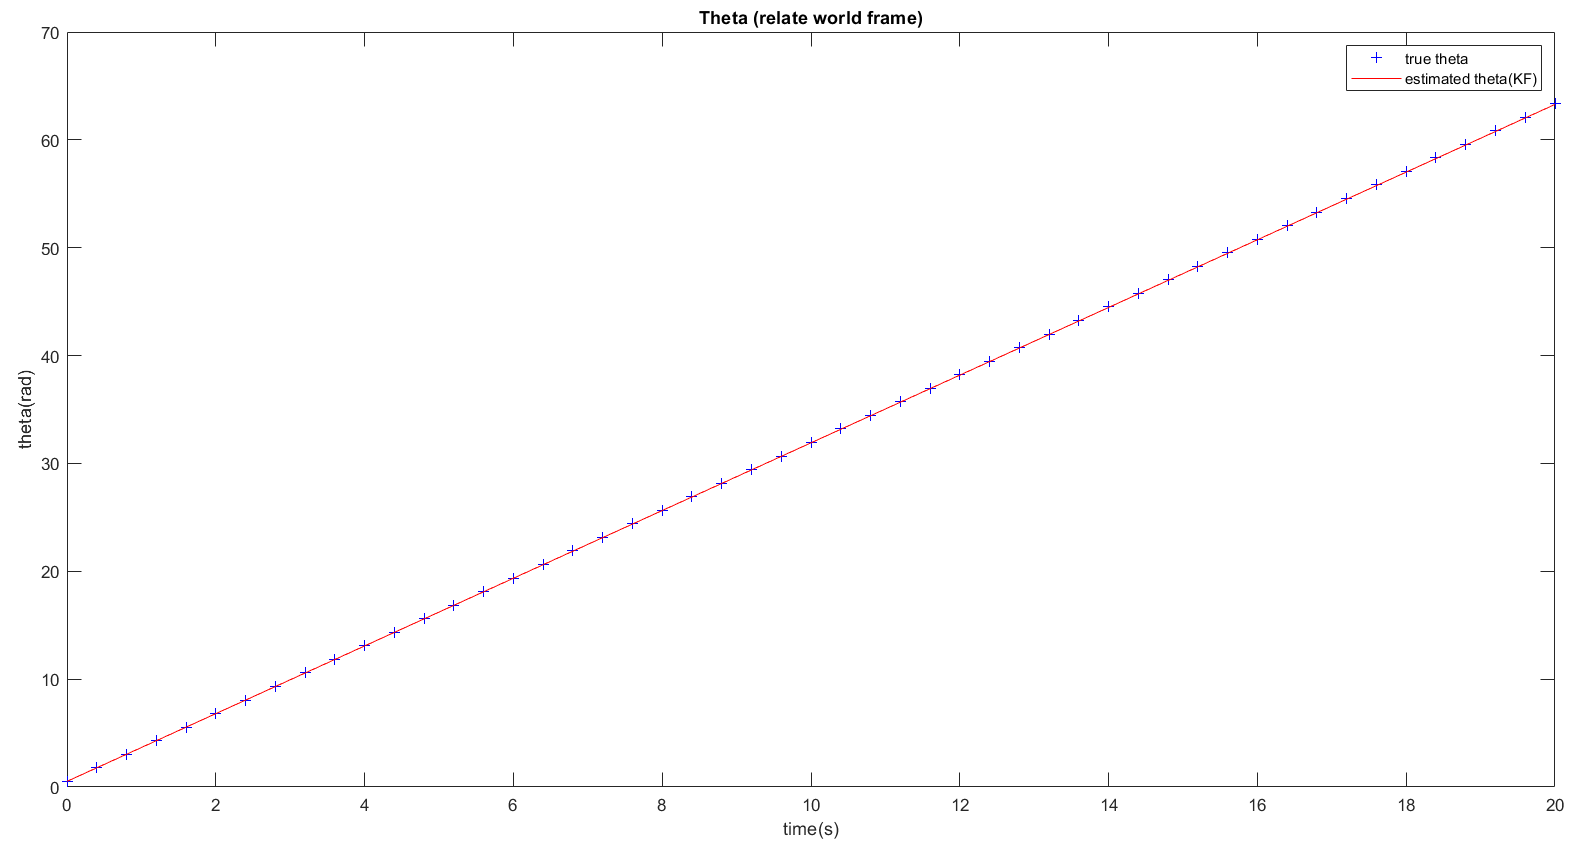

รูปที่ 23 `เปรียบเทียบม`ุมที่วัตถุเอียงเมื่อเทียบกับเฟรมโลกค่าจริงกับค่าที่ประมาณได้

                จากกราฟจะเห็นได้ว่า`ม`ุมที่วัตถุเอียงเมื่อเทียบกับเฟรมโลกที่จากการประมาณค่าผ่าน Kalman Filter มีค่าใกล้เคียงกับค่าจริง

และมีค่าเฉลี่ยของผลต่างระหว่างค่าที่ประมาณได้กับค่าจริงอยู่ที่

theta_error = mean(out.theta_error.Data(:,1))

theta_error = -0.0314

`theta_error = -0.0316 rad = -1.81 degree`

`ซึ่งจะเห็นได้ว่าความคลาดเคลื่อนที่ได้นั้นค่อนข้างน้อยแสดงว่าระบบการประมาณค่าของ Kalman Filter นั้นสามารถใช้งานได้`

### `    4.5 สรุปผลการจำลอง`

`         การจำลองการเคลื่อนที่ของวัตถุที่มีเซนเซอร์ IMU ติดอยู่ ผ่าน Simulink โดยจำลองระบบทางกายภาพใน Plant Subsystem และจำลองเซนเซอร์ IMU ใน Sensor Subsystem แล้วนำค่าที่เซนเซอร์อ่านได้มากรอง Noise และประมาณโดยใช้ Time-Invariant Kalman Filter และ Time-Variant Kalman Filter Subsystem และสุดท้ายตำแหน่งและทิศทางการหมุนที่ประมาณค่าได้นั้นมีค่าใกล้เคียงกับค่าจริงที่มาจากระบบทางกายภาพจึงสรุปได้ว่าระบบการประมาณค่าโดย Kalman Filter ที่ทำนั้นสามารถใช้งานได้`